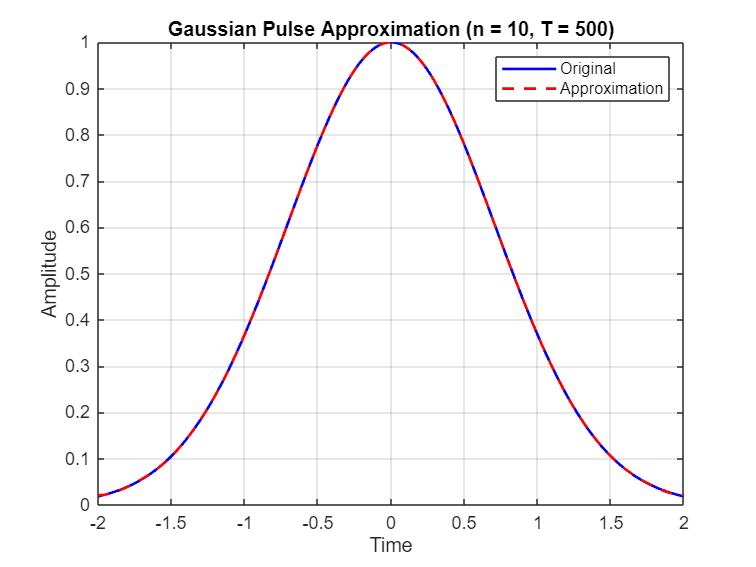

% Gaussian Pulse Fourier Series approximation for a normal function
T = 4;
t = linspace(-2, 2, 1000);
xt = exp(-t.^2);
n = 10;
[xhat, ck] = ffs(xt, t, n, T);
plot(t, xt, 'b', t, xhat, 'r--', 'LineWidth', 1.5)
legend('Original', 'Approximation')
title('Gaussian Pulse Approximation (n = 10, T = 4)')
xlabel('Time')
ylabel('Amplitude')
grid on

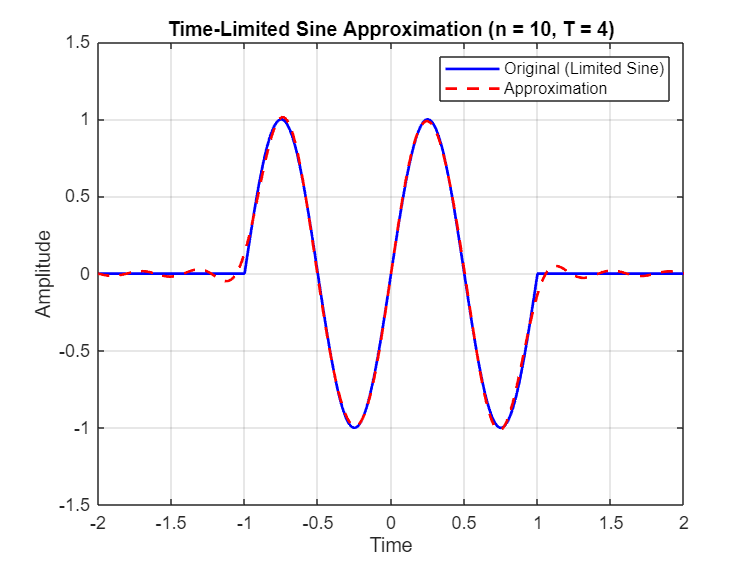

% Time-limited sine wave approximation
T = 4;
t = linspace(-2, 2, 1000);
xt = sin(2*pi*t) .* (abs(t) < 1);
n = 10;
[xhat, ck] = ffs(xt, t, n, T);
plot(t, xt, 'b', t, xhat, 'r--', 'LineWidth', 1.5)
legend('Original (Limited Sine)', 'Approximation')
title('Time-Limited Sine Approximation (n = 10, T = 4)')
xlabel('Time'), ylabel('Amplitude')
grid on

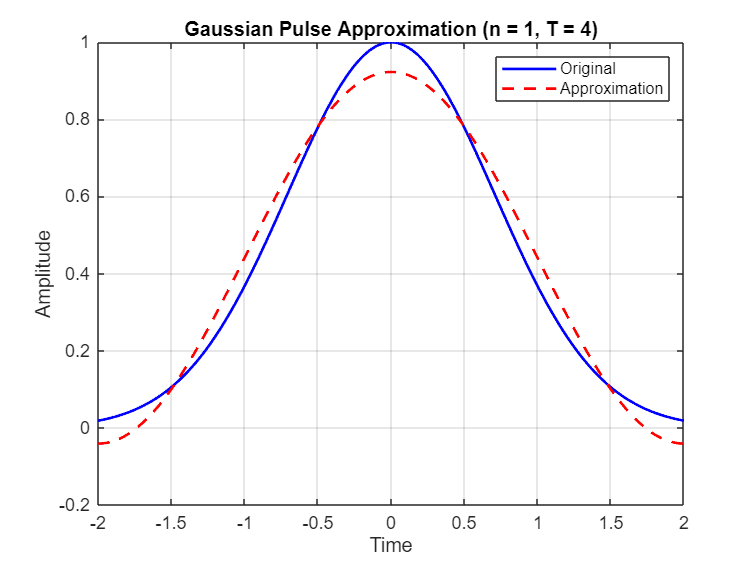

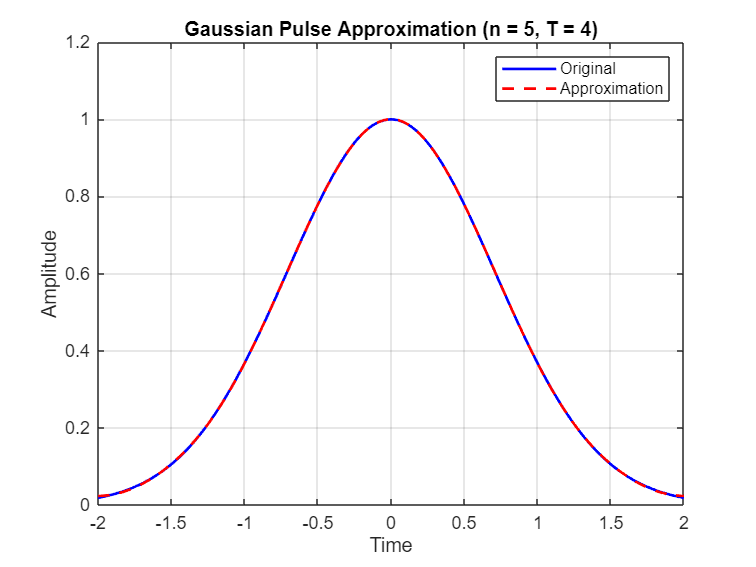

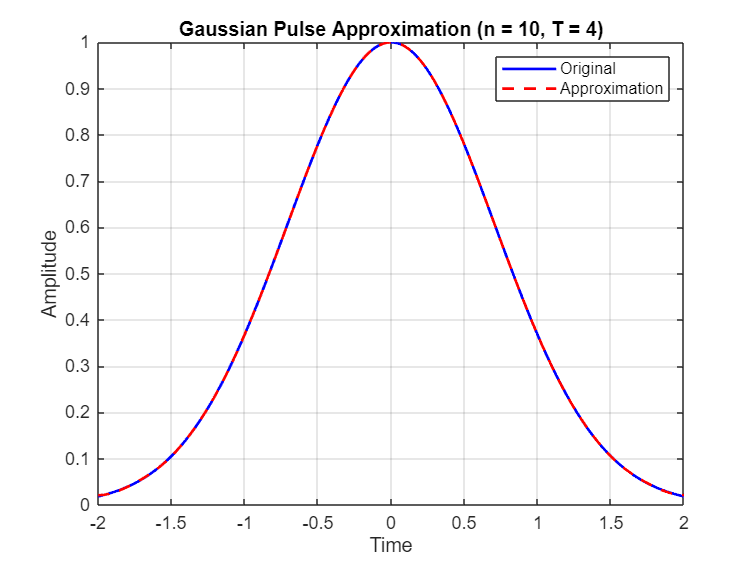

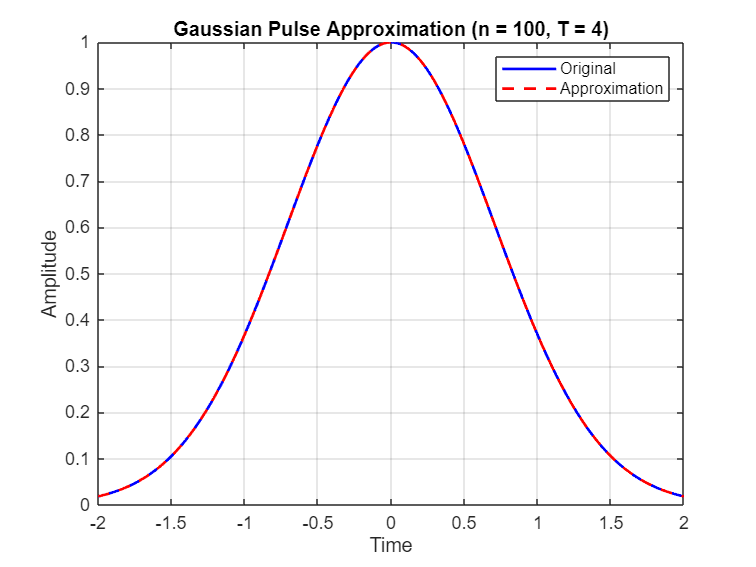

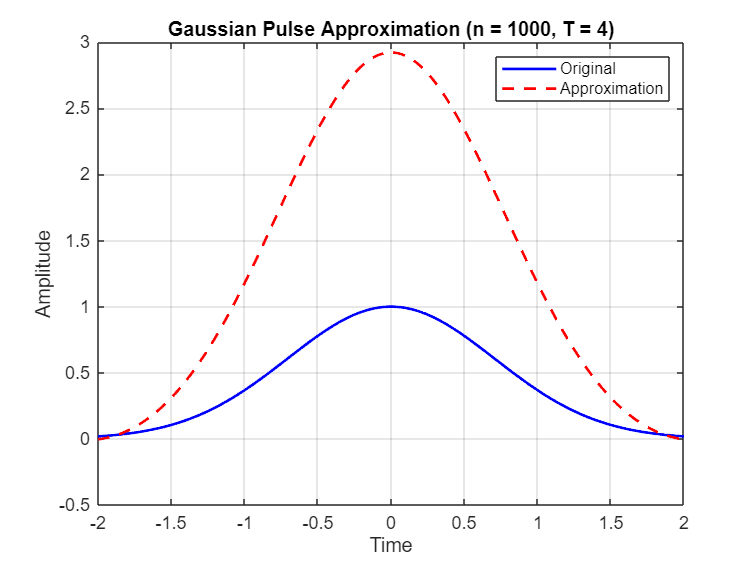

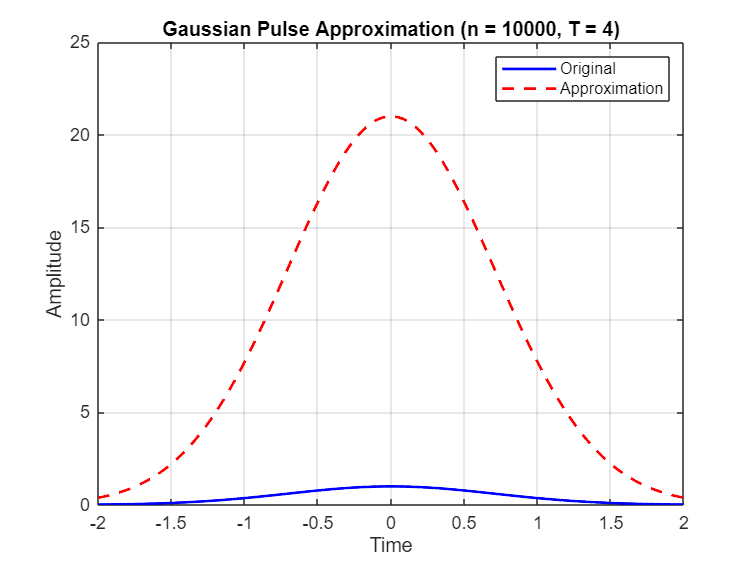

% Fixed T, Varying n
T = 4;                         
t = linspace(-2, 2, 1000);     
xt = exp(-t.^2);              
n_values = [1, 5, 10, 100, 1000, 10000];
for i = 1:length(n_values)
    n = n_values(i);
    [xhat, ck] = ffs(xt, t, n, T);  % Fourier series approximation
    figure;
    plot(t, xt, 'b', t, xhat, 'r--', 'LineWidth', 1.5);
    legend('Original', 'Approximation');
    title(['Gaussian Pulse Approximation (n = ', num2str(n), ', T = 4)']);
    xlabel('Time'); ylabel('Amplitude'); grid on;
end

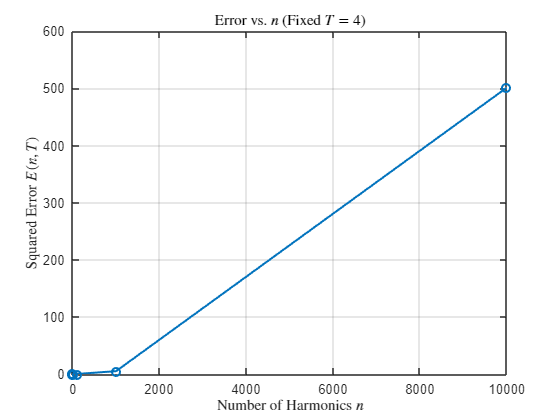

errors = zeros(size(n_values)); 
for i = 1:length(n_values)
    n = n_values(i);
    errors(i) = compute_error(xt, t, n, T);
end
% === Plot Error vs. Number of Harmonics ===
figure;
plot(n_values, errors, '-o', 'LineWidth', 1.5);
xlabel('Number of Harmonics $n$', 'Interpreter', 'latex');
ylabel('Squared Error $E(n, T)$', 'Interpreter', 'latex');
title('Error vs. $n$ (Fixed $T = 4$)', 'Interpreter', 'latex');
grid on;

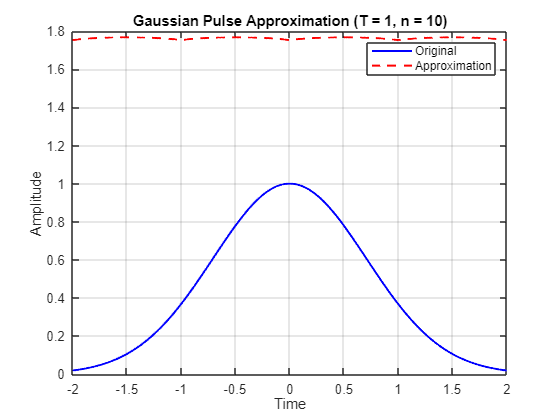

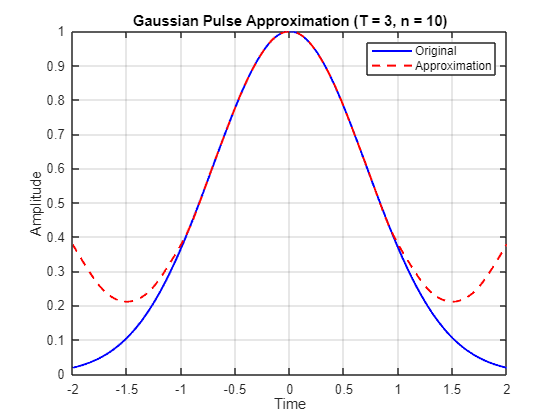

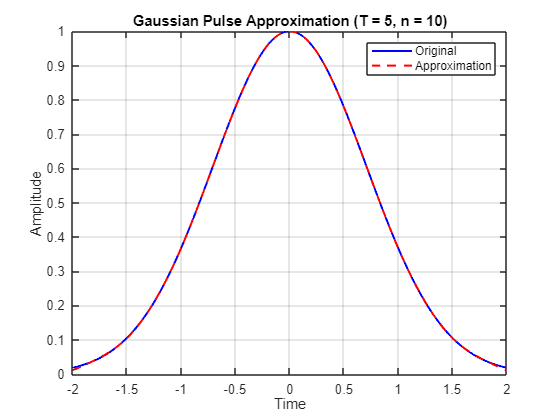

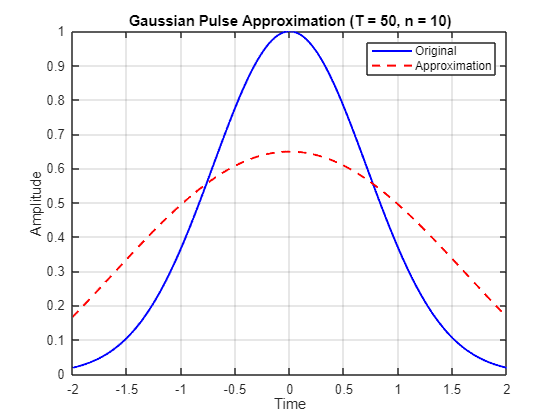

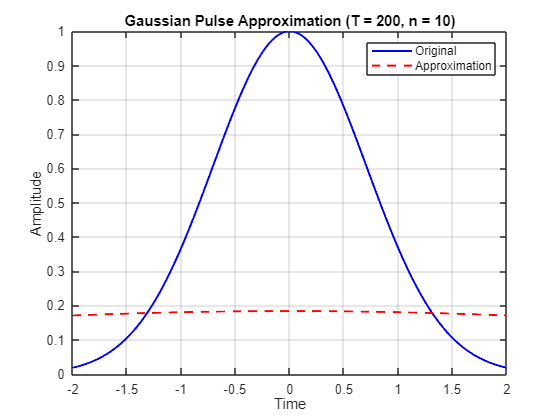

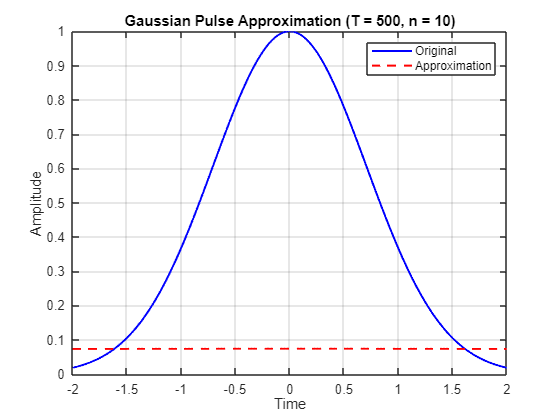

% Fixed n, Varying T
n = 10;                         
t = linspace(-2, 2, 1000);      
xt = exp(-t.^2);               

T_values = [1, 3, 5, 50, 200, 500];

for i = 1:length(T_values)
    T = T_values(i);

    [xhat, ck] = ffs(xt, t, n, T);  

    figure;
    plot(t, xt, 'b', t, xhat, 'r--', 'LineWidth', 1.5);
    legend('Original', 'Approximation');
    title(['Gaussian Pulse Approximation (T = ', num2str(T), ', n = 10)']);
    xlabel('Time'); ylabel('Amplitude'); grid on;
end

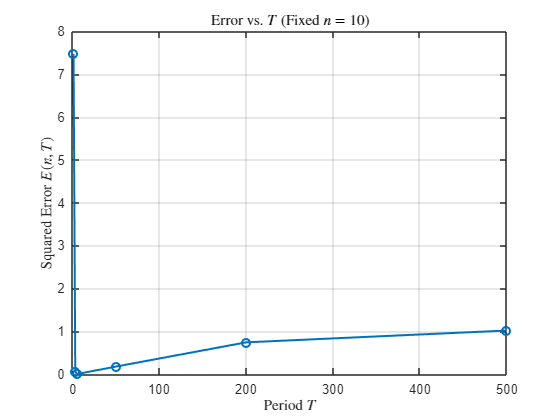

errors_T = zeros(size(T_values));             
for i = 1:length(T_values)
    T = T_values(i);
    errors_T(i) = compute_error(xt, t, n, T); 
end
% === Plot Error vs. T ===
figure;
plot(T_values, errors_T, '-o', 'LineWidth', 1.5);
xlabel('Period $T$', 'Interpreter', 'latex');
ylabel('Squared Error $E(n, T)$', 'Interpreter', 'latex');
title('Error vs. $T$ (Fixed $n = 10$)', 'Interpreter', 'latex');
grid on;